x = 1:100;

% 构造一个数组,元素为1,2,3, ...... 100
% randn(1,100)意味着生成一个1行100列的矩阵
% 矩阵元素的均值为0,方差a^2=1,且是正态分布的随机数
data = randn(1,100);
data(20:20:80) = NaN;
% data的值都是在e附近的,设置4个异常值
data(10) = -50;
data(40) = 45;
data(70) = -40;
data(90) = 50

data =     0.5377    1.8339   -2.2588    0.8622    0.3188   -1.3077   -0.4336    0.3426    3.5784  -50.0000   -1.3499    3.0349    0.7254   -0.0631    0.7147   -0.2050   -0.1241    1.4897    1.4090       NaN    0.6715   -1.2075    0.7172    1.6302    0.4889    1.0347    0.7269   -0.3034    0.2939   -0.7873    0.8884   -1.1471   -1.0689   -0.8095   -2.9443    1.4384    0.3252   -0.7549    1.3703   45.0000   -0.1022   -0.2414    0.3192    0.3129   -0.8649   -0.0301   -0.1649    0.6277    1.0933    1.1093


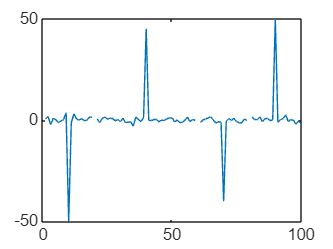

plot(x,data)


% 设置第20,40,60,80个元素为缺失值

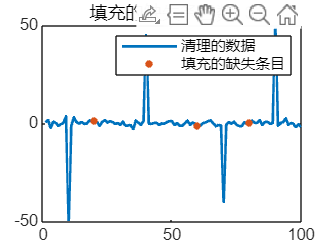

% 填充缺失数据
[cleanedData,missingIndices] = fillmissing(data,"spline");

% 显示结果
clf
plot(cleanedData,"Color",[0 114 189]/255,"LineWidth",1.5,"DisplayName","清理的数据")
hold on

% 绘制填充的缺失条目
plot(find(missingIndices),cleanedData(missingIndices),".","MarkerSize",12,...
    "Color",[217 83 25]/255,"DisplayName","填充的缺失条目")
title("填充的缺失条目数: " + nnz(missingIndices))

hold off
legend

clear missingIndices

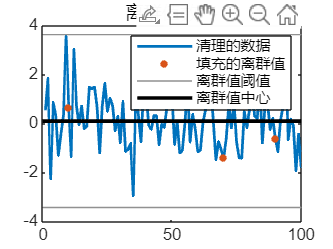

% 填充离群值
[cleanedData2,outlierIndices,thresholdLow,thresholdHigh,center] = ...
    filloutliers(cleanedData,"spline");

% 显示结果
clf
plot(cleanedData2,"Color",[0 114 189]/255,"LineWidth",1.5,"DisplayName","清理的数据")
hold on

% 绘制填充的离群值
plot(find(outlierIndices),cleanedData2(outlierIndices),".","MarkerSize",12,...
    "Color",[217 83 25]/255,"DisplayName","填充的离群值")
title("离群值数: " + nnz(outlierIndices))

% 绘制离群值阈值
plot([xlim missing xlim],[thresholdLow*[1 1] NaN thresholdHigh*[1 1]],...
    "Color",[145 145 145]/255,"DisplayName","离群值阈值")

% 绘制离群值中心
plot(xlim,[center,center],"k","LineWidth",2,"DisplayName","离群值中心")

hold off
legend

clear outlierIndices thresholdLow thresholdHigh center